# Projet 4.5 - Séparation de sources Audio

## Représentation parcimonieuse et acquisitions compressées

Fichier .mlx permettant de tester deux ou trois idées.

Attention, faites en sorte d'avoir :

- Audio Toolbox (Pour importer du son et tout c'est mieux)

- Signal Processing Toolbox 

- Wavelet toolbox (Pour générer les dictionnaires (?))

- Statistics and Machine Learning Toolbox (Pour les algorithmes spécifiques txpe ICA, clustering, etc..)

- RIP l'espace libre sur vos disques durs.

## Étape 1 - Avoir une source et la caractériser

Déjà, on va ouvrir un signal sur matlab. 

On peut utiliser n'importe quel signal audio. Ici, je ne prendrai que les 20 premières secondes d'un signal , 

dans le souci de soulager nos processeurs, déjà très sollicités par l'UI de Matlab.

J'ai P=2 observations de mon mélange (les deux mono qui forment le stereo), et **2** sources. (On pourra pousser à 3 sources quand ça marchera)

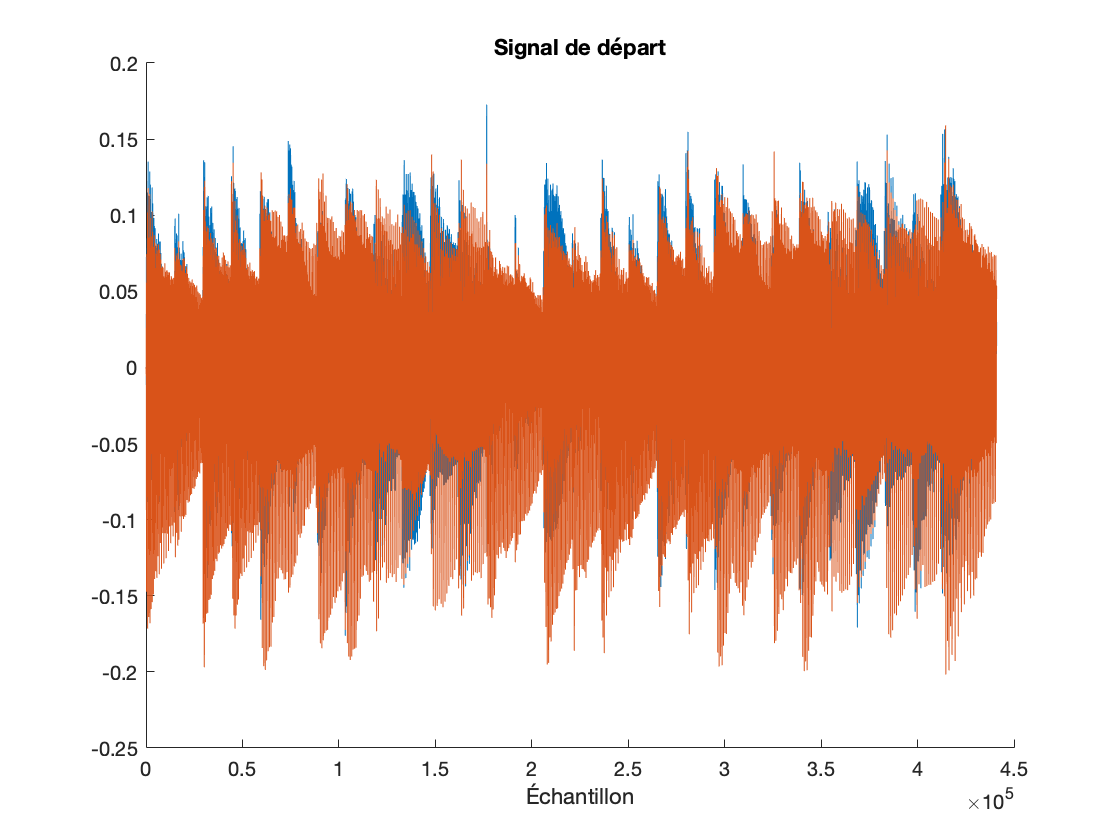

clear all
[~,Fs] = audioread('2_voix.wav');
samples = [1,10*Fs];     %Je ne prends que les 10 premières secondes, sinon mon ordi est à la rue
clear y Fs
[x,Fs] = audioread('2_voix.wav',samples);




x1 = x(:,1);  %J'ai séparé les deux signaux, parce que Stereo
x2 = x(:,2);
%x1 = x1(1:4:end);
%x2 = x2(1:4:end);

%x = [x1, x2];

%Nombre d'éléments du signal
T = length(x);
%Durée d'observation, en secondes
Tobs = T / Fs;
%Plot
figure;
title('Signal de départ')
xlabel("Échantillon")
hold on;
plot(x1);
plot(x2)
hold off

Dans la section suivante, j'importe les différentes sources individuelles pour pouvoir les comparer à nos solutions potentielles


[s1, Fs] = audioread("bass.wav", samples);
[s2, Fs] = audioread("chords.wav", samples);
[s3, Fs] = audioread("arpeges.wav", samples);
%Ce sont nos sources au départ, ça peut servir


s1 = s1(:,1);
s2 = s2(:,1);
s3 = s3(:,1);
%Je ne prends qu'un canal
        
%         
% S(1,:)=s1;
% S(2,:)=s2;
% S(3,:)=s3;  %On génère notre matrice permettant d'avoir une fenetre avec le code tout fait
% 



## Étape 2 - Parcimonier... si on peut le dire comme ça.

Je vais maintenant transformer ce sur quoi je travaille. En effet, je vais passer dans un autre domaine, et utiliser la ***modified discrete cosine transform. ***

On qualifiera cette transformée de ***sparsifying linear transform --> ***Elle va rendre nos données parcimonieuses, ou du moins on l'espère. 

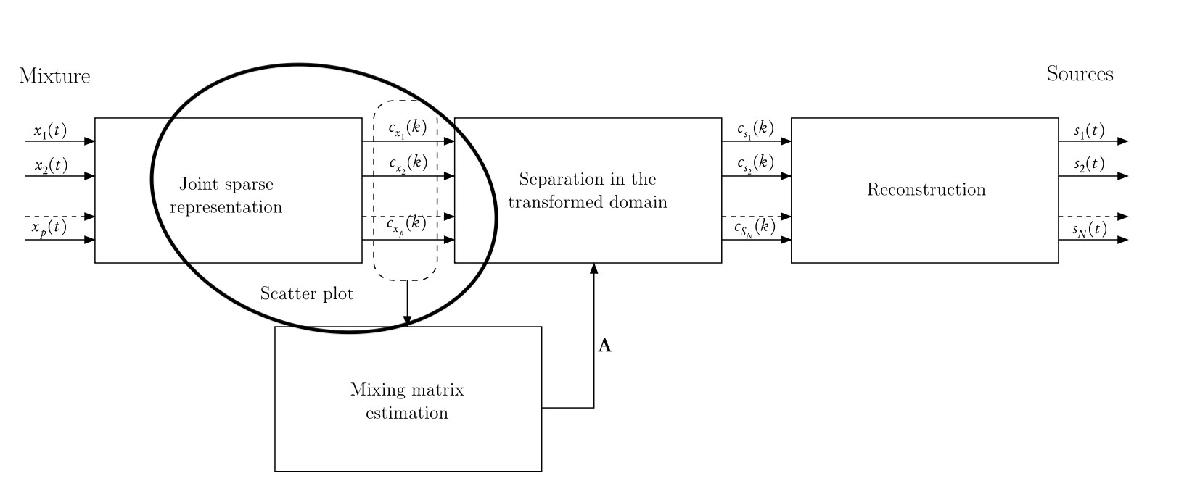

En effet, dans les faits les signaux audio sont tout sauf parcimonieux à la base. 

C'est un problème à dominantes multiples (Les sources sont actives simultanément), ce qui rend la chose bien plus difficile.  

*La section suivante contient le code utilisant la MDCT*

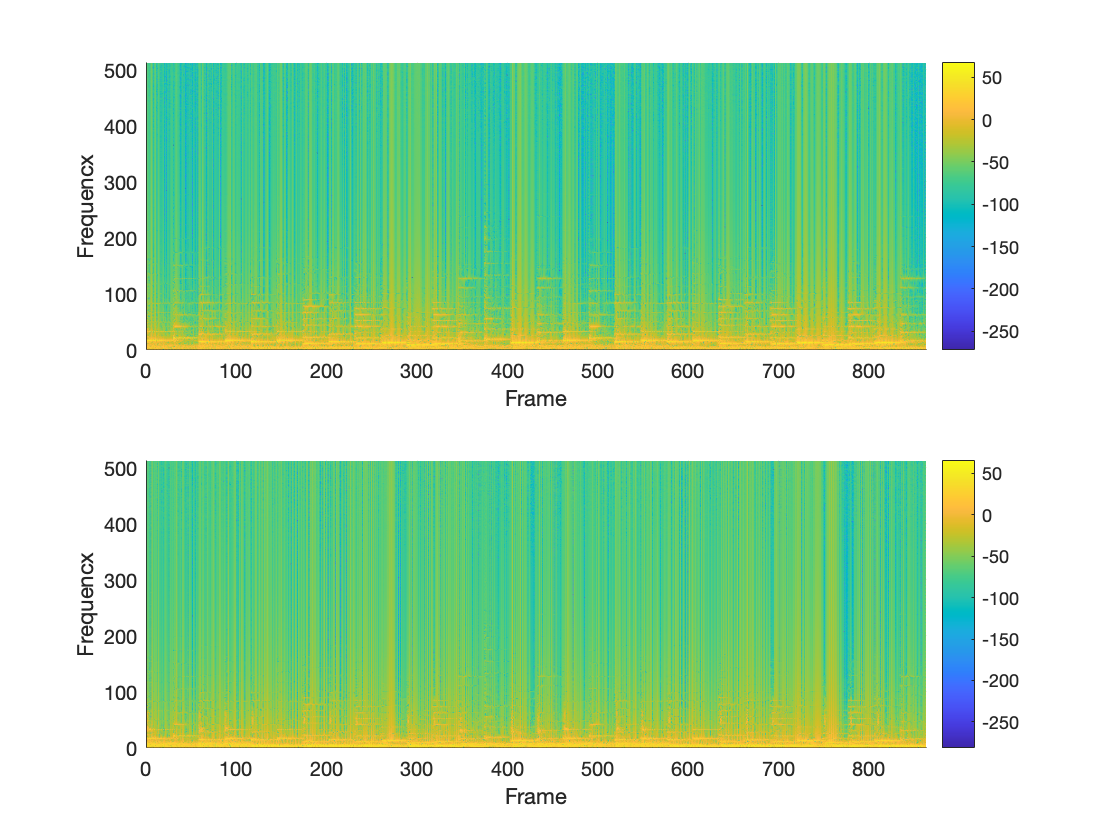

win_size = 1024; 
% On peut déjà commencer par une fenêtre rectangulaire. 
win = rectwin(win_size);


cx1 = mdct(x1,win);         % kbdwin renvoie une matrice de la taille de la fenetre sur 2 par
                                            %   ceil(2*length(x1)/1024) +1 
cx2 = mdct(x2, win);
coeff_size = size(cx1);  %Permet de se rendre compte que mdct renvoie une matrice, allez savoir..




subplot(2,1,1);
surf(20*log10(cx1.^2),'EdgeColor','none'); %plot une surface
view([0 90])
xlabel('Frame')
ylabel('Frequencx')
axis([0 size(cx1,2) 0 size(cx1,1)])
colorbar
subplot(2,1,2);
surf(20*log10(cx2.^2),'EdgeColor','none'); %plot une surface
view([0 90])
xlabel('Frame')
ylabel('Frequencx')
axis([0 size(cx2,2) 0 size(cx2,1)])
colorbar

Cette cellule ci utilise la STFT (short-timed Fourier Transform), avec la fonction spectrogram() 

win_size = 1024; 
% On peut déjà commencer par une fenêtre rectangulaire. 
win = rectwin(win_size);


[S1,F1,T1] = spectrogram(x1,win,0);   %STFT
[S2,F2,T2] = spectrogram(x2,win,0);    %STFT, mettre win_size/2 à la place de 0
S = [S1(:) S2(:)];


Tracer l'histogramme permet de voir si on a une distribution parcimonieuse.

 cf 10.3 du Chap 10 - Handbook blind source separation

Ici, nos coefficients de transformée sont complexes, j'affiche donc la valeur absolue de ces coefficients.

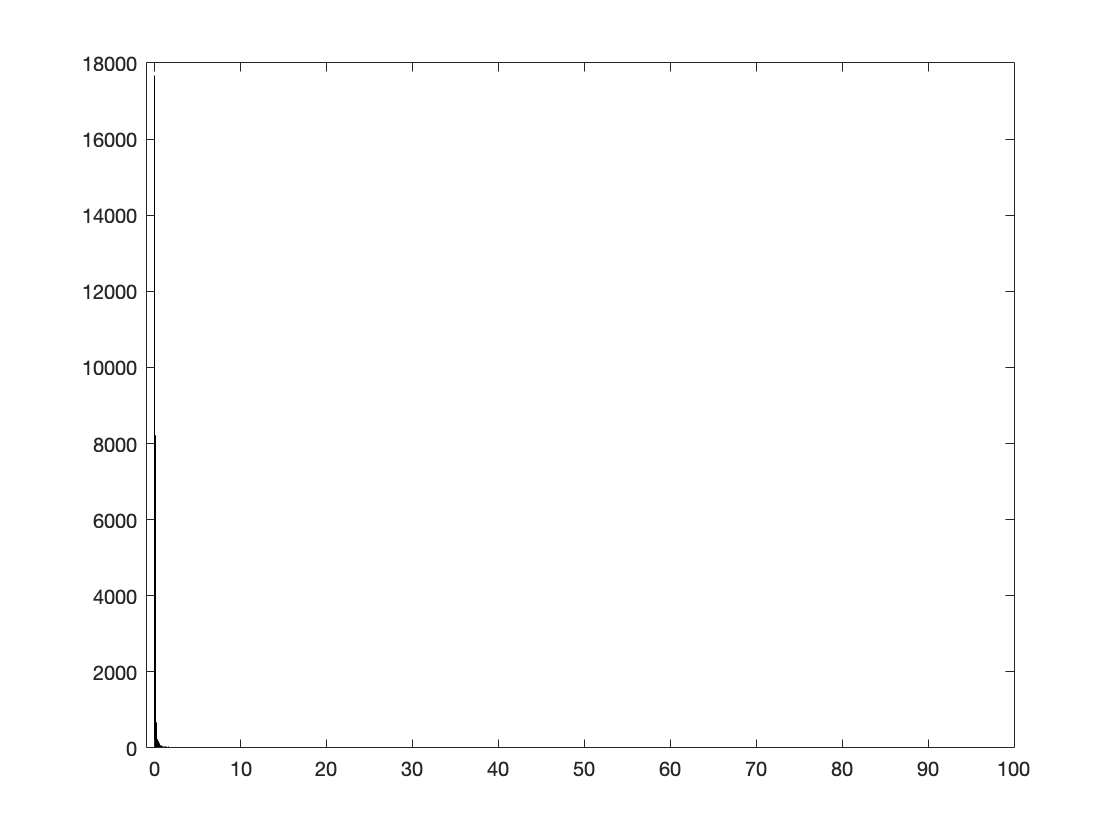

figure;
histogram(abs(S1),10000);    %Assez peu représentatif, on ne se rend pas bien compte de ce qu'il se passe
                            % de ce qu'il se passe dans voisinage plus
                            % petit de 0
xlim([-1 100])  

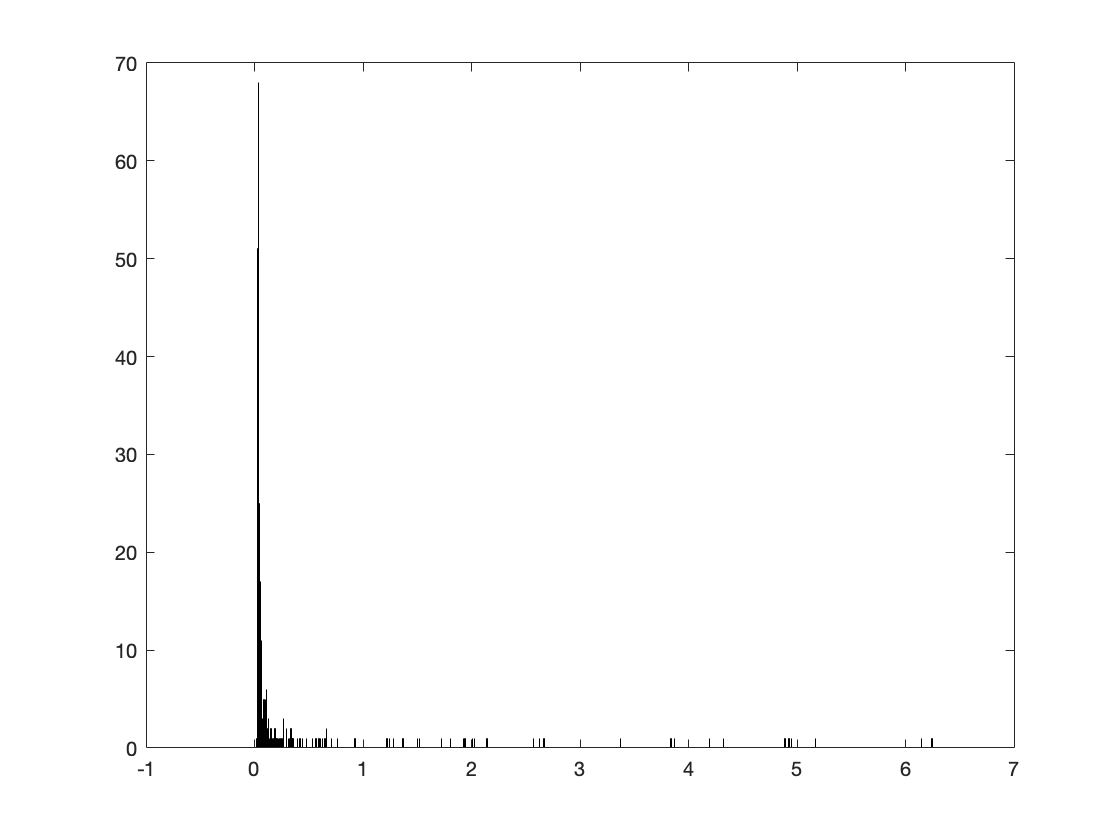



figure;  %Pour regarder de plus près autour de 0
histogram(abs(S1(1:500)),10000);
xlim([-1 7])

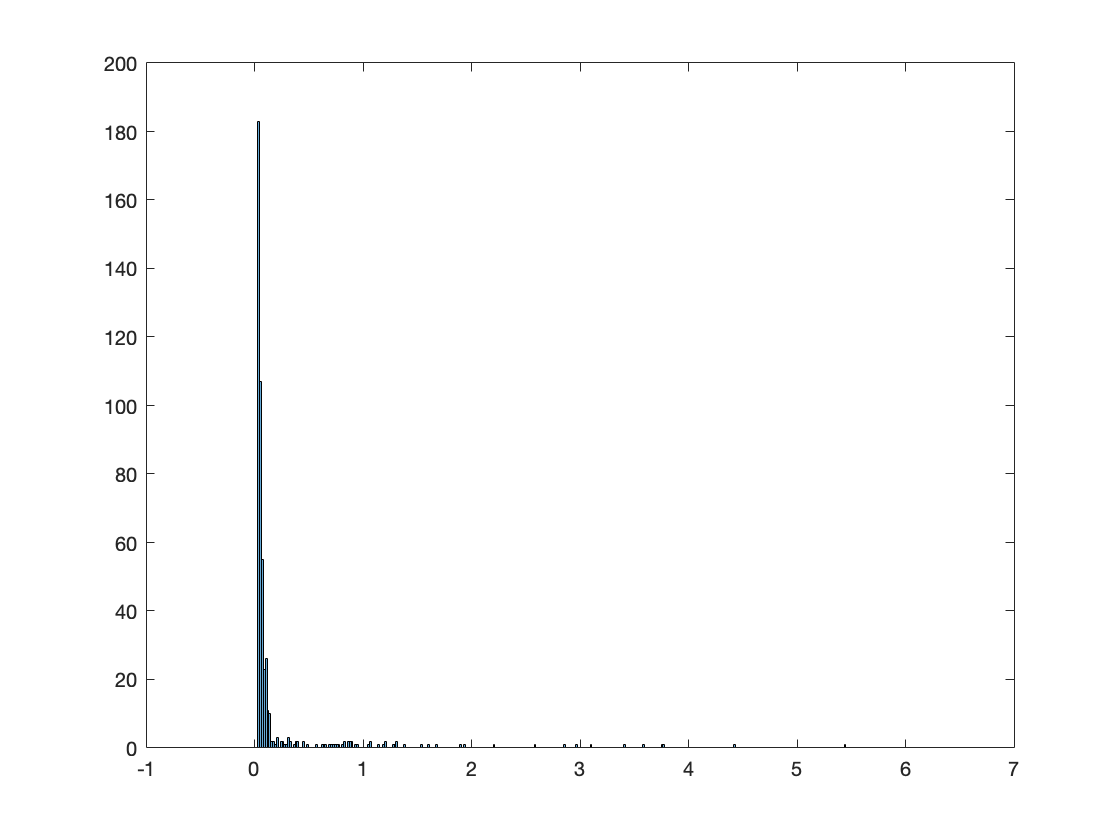

figure;  %Pour regarder de plus près autour de 0
histogram(abs(S2(1:500)),1000);
xlim([-1 7])

 **Etant donné qu'on a pic pour des valeurs très petites, on peut se dire que c'est le cas : **

**on a plein de valeurs considérées comme quasi-nulles. **

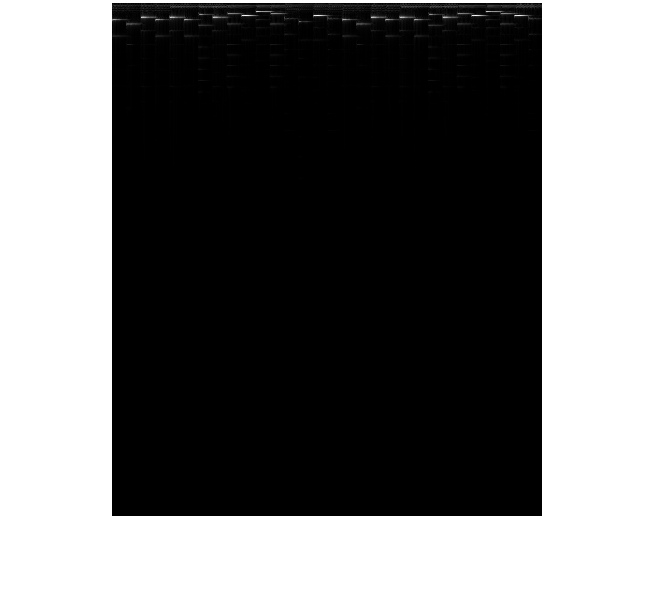


%Je trouvais sympa, pour montrer la parcimonie, de visionner des
%images.

figure;
M1 = mat2gray(abs(S1));
imshow(M1);

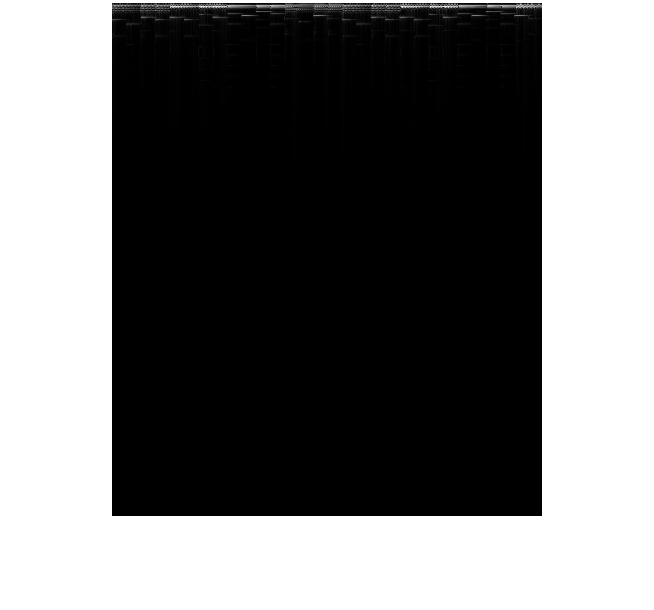


figure;
M2 = mat2gray(abs(S2));
imshow(M2);

A présent, visualisons nos Scatter plot, et voyons s'ils ont l'air cohérents !

***MDCT***

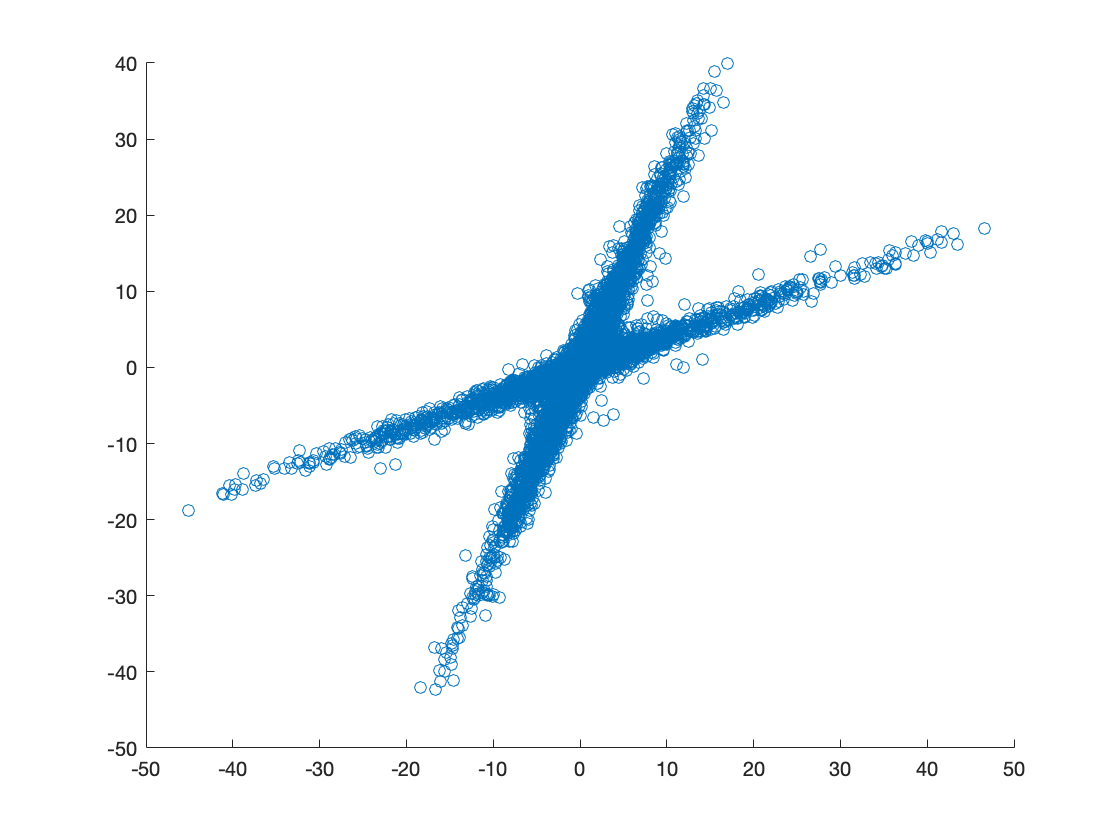

%Attention au sens, pour le scatter plot

temp = ceil(2*length(x1)/1024) + 1 ;
c1 = reshape(cx1,[win_size*temp/2,1]);

c2 = reshape(cx2,[win_size*temp/2,1]);    

figure;
scatter(c1,c2);

***STFT***

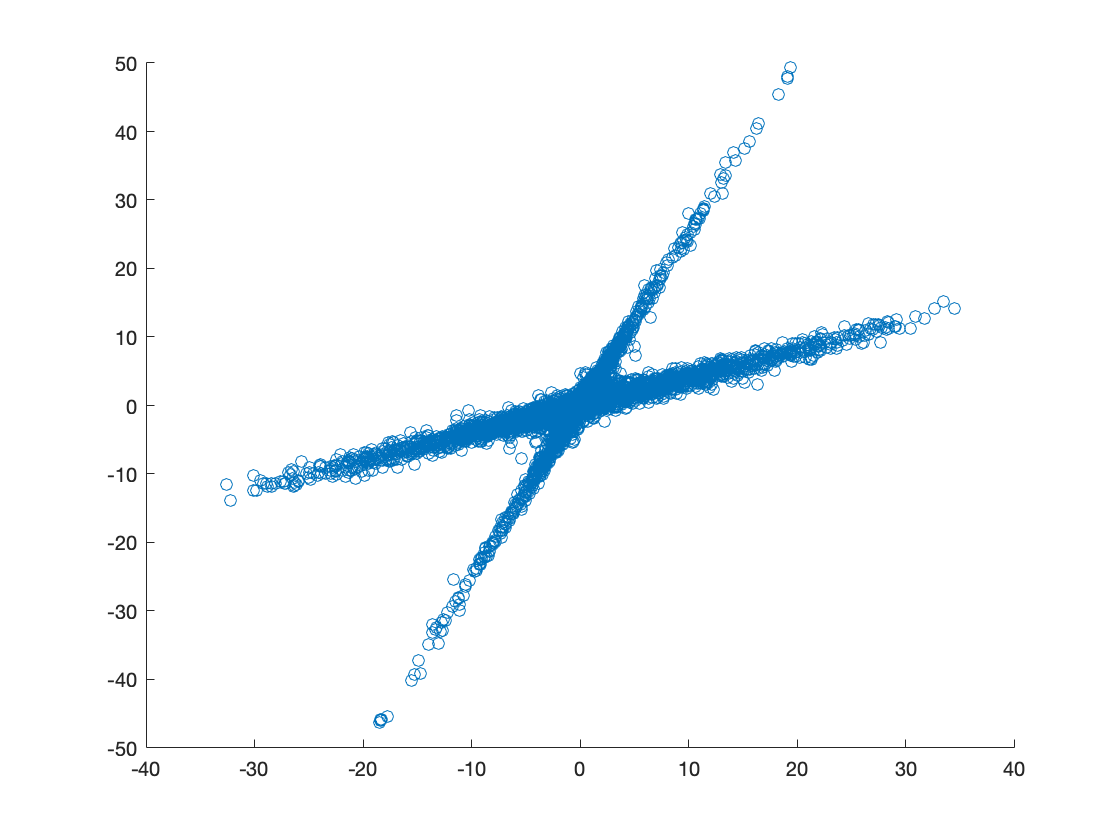

figure;
scatter(S2(:),S1(:));   %Wah l'astuce, ça flatten 

Dans l'idée, on se rend compte que les directions, extrêmement  discernables lorsqu'il n'y a que deux sources, 

sont bien plus fine sur le scatterplot de la STFT. Ça sera surement la solution que l'on retiendra. 

## Étape 3 - Estimation de la *Mixing Matrix*

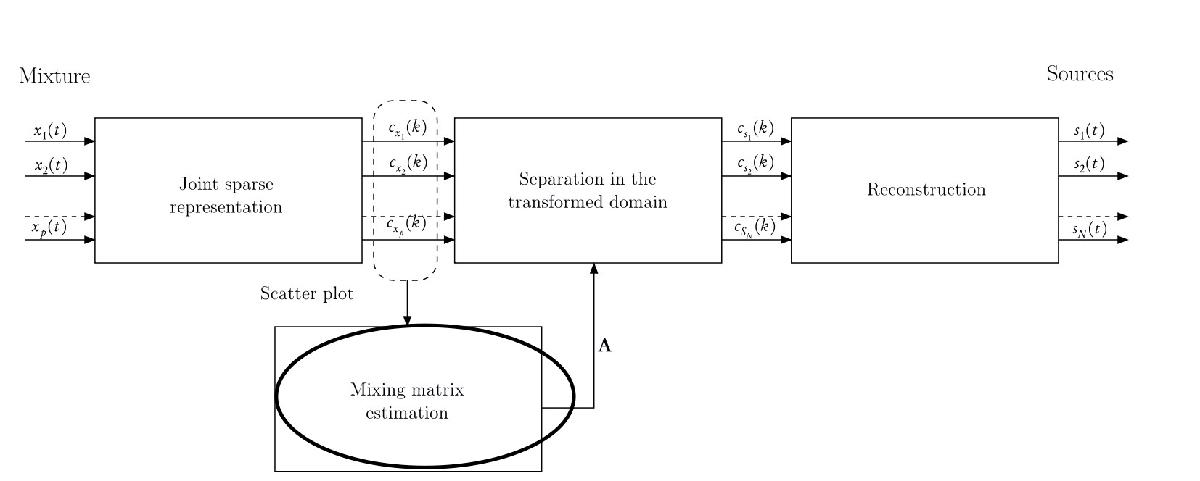

On doit ici estimer la mixing matrix, mais qu'est-ce donc que cela ?

Une matrice, certainement. C'est la matrice qui va représenter le mélange de nos différentes sources, qui composent notre signal final. 

Pour coller aux notations du Handbook, je vais construire la matrice Cx, qui correspond à : 

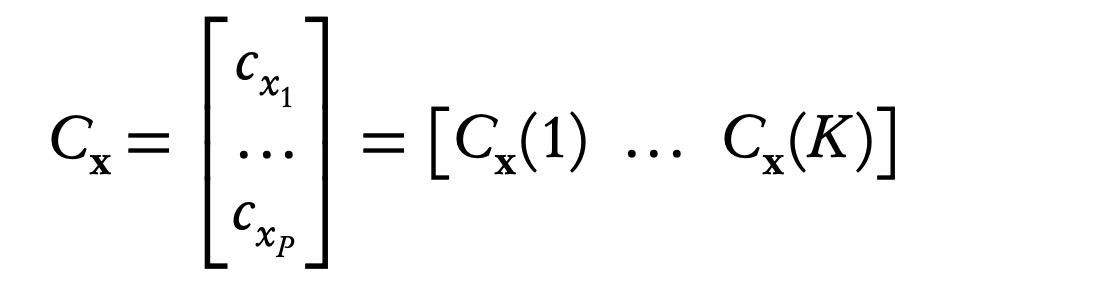

cf équation 10.12

Le but est d'estimer la n-ième colonne de A, et la direction qui va avec. 

Cx = [abs(S1(:))' ;  abs(S2(:))'];   % Pas certain que je doive utiliser le module, je perd une partie de l'information...
%On doit normalement avoir une matrice à deux lignes, et... plein de
%colonnes. 
Csize = size(Cx)

Csize =            2      220590


rho = zeros([1 Csize(2)]);
theta = zeros([1 Csize(2)]);


for k = 1:length(Cx)
    theta(k) = atan(Cx(2,k)/Cx(1,k));
    rho(k) = sqrt(abs(Cx(2,k))^2  + abs(Cx(1,k))^2);
    if theta(k)<0
        theta(k) = theta(k) + pi;
        rho(k) = -sqrt(abs(Cx(2,k))^2  + abs(Cx(1,k))^2);
    end           
end


ratio = theta./(abs(rho));

***Affichages des directions trouvées***

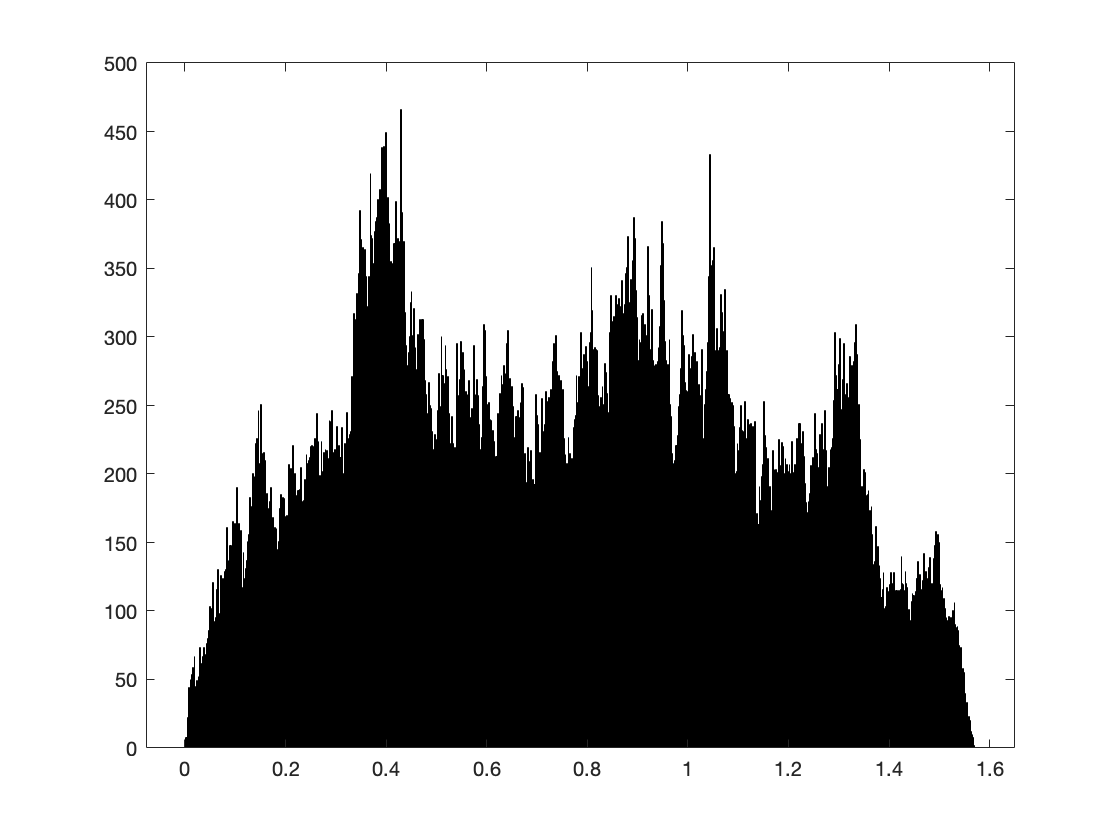

histogram(theta,1000)

Fichtre, nous n'allons pas allé bien loin avec ça ! 

Heureusement, le handbook nous propose d'utiliser un histogramme pondéré, plutôt qu'un histogramme sorti du chapeau en espérant trouver des directions.

On va donc définir notre fonction de lissage, et l'appliquer à nos valeurs de thêta.  cf équation 10.35

% smoothing_win = parzenwin(win_size);
% theta_l = linspace(0,pi,win_size);
% H = linspace(0,0,win_size);
% for l =1:win_size
%     for k = 1:Csize(2)
%         H(l) = H(l) + rho(k)*smoothing_win(floor(1024*(theta_l(l)-theta(k))));
%     end
% end


Bon ok j'avoue que j'ai pas tout compris, mais je fais l'effort, promis. 

Déjà, pour se rendre compte du fait qu'on ne dit pas forcément de bétises, on peut tracer l'amplitude en fonction de l'angle : 

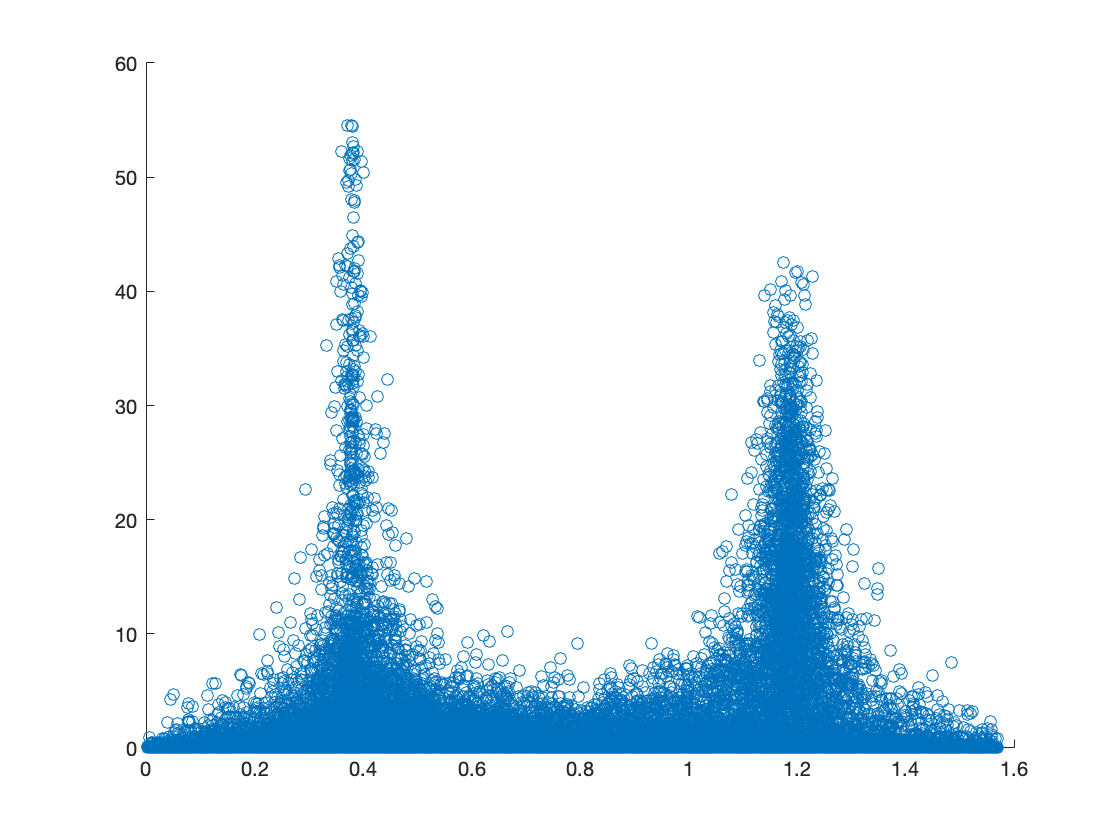


figure;
scatter(theta,rho)

On voit bien deux directions qui se démarquent. C'est sympa ! 

## Étape 4 - Séparation en composantes indépendantes

Selon le 2- du 10.1 du Chap 10 - Handbook blind source separation,

on peut appliquer un clustering algorithm sur le scatter plot (Mais le scatter plot de quoi?), mais habituellement, on utilise plutôt un algorithme de ICA (independent components analxsis). 

J'ai chopé des petites vidéos yt sxmpa dessus.

## Test


theta_l(1)

Unrecognized function or variable 'theta_l'.